#     Taller de Simulación Numérica

*F. Pena, P. Quintela*

## Tema 3. El método de diferencias finitas. EDO no lineal

Consideramos el siguiente problema de contorno no lineal (P):


$$\left\{\begin{array}{ll}y'' = F(x,y,y') = u(x) + v(x)y^m+w(x)y',\\-y'(a)+h_ay(a)=y_a,\\y'(b)+h_by(b)=y_b.\end{array}$$


### Algoritmo de iteración funcional

Se trata de obtener un punto fijo del operador $\mathcal{F}:y_k\in\mathcal{C}^2([a,b])\mapsto y\in\mathcal{C}^2([a,b])$ definido por:

    $y=\mathcal{F}(y_k)$* es la solución de *$y'' = u(x) + v(x)y_k^{m-1}\,y+w(x)y'$* cumpliendo las condiciones de contorno de *[(P)](about:blank<#M_2CC8D053>)*.*

Si definimos $\tilde{v}(x) = v(x)y_k^{m-1}$, entonces la EDO lineal $y'' = u(x) + \tilde{v}(x)y+w(x)y'$ tendrá solución única en las condiciones dadas en [Keller](https://projecteuclid.org/journals/bulletin-of-the-american-mathematical-society-new-series/volume-72/issue-4/Existence-theory-for-two-point-boundary-value-problems/bams/1183528184.full). En particular, si $v > 0$ y $m$ es un entero impar, entonces $\tilde{v}>0$ (en otro caso, habrá que garantizar que $y_0>0$).

El paso $k$ del algoritmo de iteración funcional consiste en:

- Sea $y_k\in\mathcal{C}^2([a,b])$ dado.

- Se calcula $y_{k+1}=\mathcal{F}(y_k)$.

- Si $\|y_{k+1}-y_k\|<\varepsilon$ ó $\|y_{k+1}''-u-vy_{k+1}^m - wy_{k+1}'\|<\varepsilon$ hay convergencia; si no, sigue iterando.

### Implementación del algoritmo

La función [`dfif`](matlab:open('./dfif.m')) implementa el cálculo de la solución del problema discreto. Sus argumentos de entrada son:

- La estructura `F,` con tres funciones anónimas `u(x)`, `v(x)` `y` `w(x)` con argumentos el vector `x` de puntos de discretización, y el exponente `m`.

- La estructura `bc,` que define las condiciones de contorno:

                  `bc.blk_a` es verdadero si hay una condición Dirichlet en $x=a$: *y*(`bc.a`) = `bc.ya`;

                  `bc.blk_a` es falso en otro caso:  -*y'*(`bc.a`) = `bc.ya` - `bc.ha` *y*(`bc.a`).

                  `bc.blk_b` es verdadero si hay una condición Dirichlet en $x=b$: *y*(`bc.b`) = `bc.yb`;

                  `bc.blk_b` es falso en otro caso:   *y'*(`bc.b`) = `bc.yb` - `bc.hb` *y*(`bc.b`).

- La estructura `nl,` que define el iterante inicial `yk`, el maximo de iteraciones `maxit`, y la tolerancia `tol`.

El resultado es:

- El vector de puntos de discretización, `x`, 

- El vector de valores de la solución aproximada en los puntos anteriores, `y`. 

- El número de iteraciones realizado `k`.

**Atención:** La función `vIF` (que implementa la antedicha $\tilde{v}$) se declara **dentro** de `dfif` para que pueda acceder a la variable `nl.yk`, actualizada en el bucle iterativo.

### Ejercicio 3.1. Test académico para iteración funcional

Considera el problema de contorno:


$$\left\{\begin{array}{ll}y''(x) = u(x)+y^m,\\-y'(0)+y(0)=1,\\y'(1) +y(1)= 2\text{e}+\cos(1)-\sin(1),\end{array}$$


siendo $u(x) = \mathrm{e}^x-\cos(x)-\left(\mathrm{e}^x+\cos(x)\right)^m$, con solución exacta $y(x) = \exp(x)+\cos(x)$.

- **Representa grá**`fi`**camente la solución exacta y la aproximada.**

Utiliza pasos $\Delta x= 0.1$ y $\Delta x = 0.01$. Identifica las gráfica e incluye en la leyenda las iteraciones realizadas.

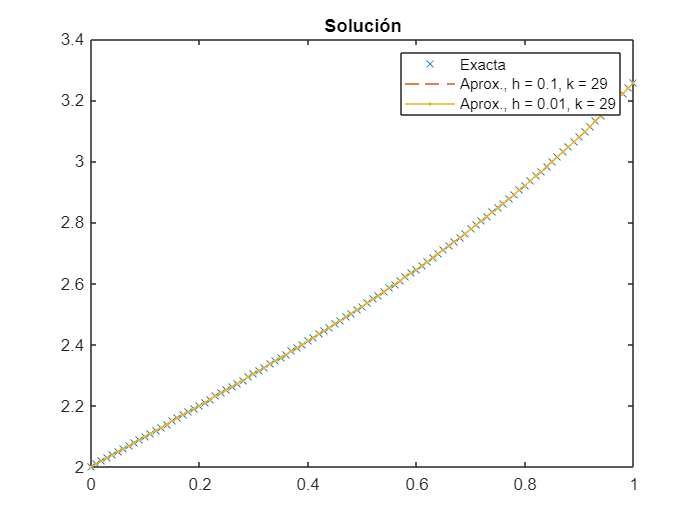

%Solucion
clear all
m = 2;
F = struct('u', @(x) exp(x)-cos(x)-(exp(x)+cos(x)).^m, ...
    'v', @(x)  ones(size(x)), ...
    'w', @(x) zeros(size(x)), ...
    'm', m);
bc = struct('blk_a', false, 'a', 0, 'ya', 1,                      'ha', 1, ...
    'blk_b', false, 'b', 1, 'yb', 2*exp(1)+cos(1)-sin(1), 'hb', 1);

%h = 0.1
n = (bc.b-bc.a)/0.1;
nl = struct('yk', ones(1,n+1), 'maxit', 400, 'tol', 1.e-6);
[x1, y1, k1] = dfif(F, bc, n, nl);

%h = 0.01
n = (bc.b-bc.a)/0.01;
nl = struct('yk', ones(1,n+1), 'maxit', 400, 'tol', 1.e-6);
[x2, y2, k2] = dfif(F, bc, n, nl);

%grafica
sol = @(x) exp(x) + cos(x);
plot(x2,sol(x2),'x', ...
    x1,y1,'--', ...
    x2,y2,'.-')
title('Solución')
legend('Exacta', ['Aprox., h = 0.1, k = '  num2str(k1)], ...
    ['Aprox., h = 0.01, k = ' num2str(k2)])

- **Calcula la norma **$L^{\infty}(a,b)$** discreta del error absoluto y relativo para **$m\in [1, 1.4\ldots3]$**.**

Crea dos funciones [`normaInf`](about:blank<#M_05D4D892>) y [`normaInfR`](about:blank<#M_C940B076>) al final de este *script* que hagan el cálculo de las normas. Imprime el número de iteraciones que necesita para cada $m$.

% Solucion con h=0.01; lo demás es idéntico.
[xh, yh, k] = dfif(F, bc, n, nl);

disp(['Norma L_inf discreta del error absoluto: ' num2str(normaInf(xh,yh,sol))])

Norma L_inf discreta del error absoluto: 1.3264e-05


disp(['Norma L_inf discreta del error relativo: ' num2str(normaInfR(xh,yh,sol))])

Norma L_inf discreta del error relativo: 1.9677e-05


disp(['Norma L2 discreta del error absoluto: ' num2str(norma2(xh,yh,sol))])

Norma L2 discreta del error absoluto: 5.2998e-06


**Observación para la clase:** se comprueba que el número de iteraciones aumenta con $m$, hasta que deja de converger con $m\geq 2.5$. Se puede modificar el código de `dfif` para ver una gráfica de la norma de los iterantes. Basta incluir en el original las líneas de código señaladas aquí con `%<=`:

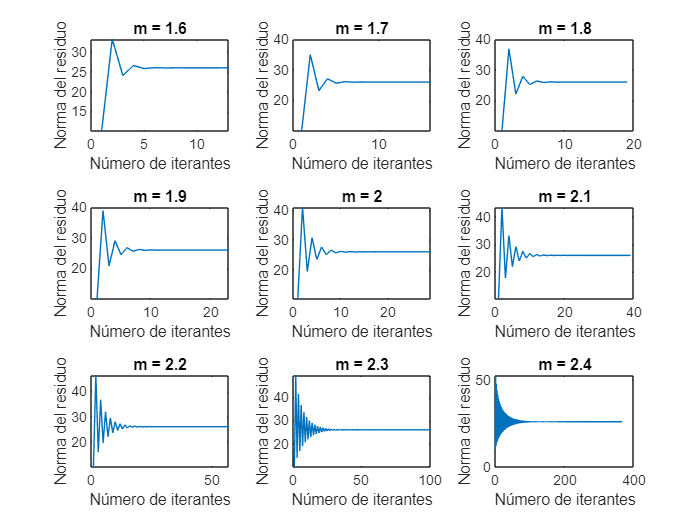

tiledlayout('flow')
for m=1.6:0.1:2.4
    nexttile
    F = struct('u', @(x) exp(x)-cos(x)-(exp(x)+cos(x)).^m, ...
        'v', @(x)  ones(size(x)), ...
        'w', @(x) zeros(size(x)), ...
        'm', m);
    bc = struct('blk_a', false, 'a', 0, 'ya', 1,                      'ha', 1, ...
        'blk_b', false, 'b', 1, 'yb', 2*exp(1)+cos(1)-sin(1), 'hb', 1);

    n = 100;
    nl = struct('yk', ones(1,n+1), 'maxit', 600, 'tol', 1.e-6);

    [xhm, yhm, km] = dfifmod(F, bc, n, nl);
    title(['m = ',num2str(m)])

end

- **Calcula la norma **$H^1(a,b)$ **discreta del error absoluto.**

Crea una función [`normaH1`](about:blank<#M_8B162C27>) al final de este *script* que haga el cálculo.

%Solucion. Esto es la integral en L2 de la derivada aproximada. Es decir,
%primero aproximamos y', luego calculamos la integral numérica.
%Solucion
m = 2;
F = struct('u', @(x) exp(x)-cos(x)-(exp(x)+cos(x)).^m, ...
    'v', @(x)  ones(size(x)), ...
    'w', @(x) zeros(size(x)), ...
    'm', m);
bc = struct('blk_a', false, 'a', 0, 'ya', 1,                      'ha', 1, ...
    'blk_b', false, 'b', 1, 'yb', 2*exp(1)+cos(1)-sin(1), 'hb', 1);

%h = 0.1
n = (bc.b-bc.a)/0.1;
nl = struct('yk', ones(1,n+1), 'maxit', 400, 'tol', 1.e-6);
[x1, y1, k1] = dfif(F, bc, n, nl);

sol = @(x) exp(x) + cos(x);
[xh, yh, ~] = dfif(F, bc, n, nl);
disp(['Norma H1 discreta del error absoluto: ' num2str(normaH1(xh,yh,sol))])

Norma H1 discreta del error absoluto: 0.21153


### Ejercicio 3.2. Balance de masa de un reactor no lineal (iteración funcional)

Considera el problema:


$$\left\{\begin{array}{l}
c''=\frac{\gamma}{D} c^m+ \frac{U}{D}\,c' ,\ x\in[0,L]\\
 -c'(0) +\frac{U}{D}c(0)= \frac{U}{D}c_{in} ,\\
c'(L) = 0.
\end{array}$$


- **Resuelve el problema anterior** **mediante diferencias finitas.** 

Usa los siguientes datos: $L=10\, \text{m}$, $D=1\,\text{m}^2/\text{h}$, $U=1\,\text{m}/\text{h}$, $\gamma=0.2$, $c_{in}=100\,\text{mol}/\text{m}^3$, y un paso $\Delta x = 0.125\,\text{m}$. 

% Solución. Atención: m está dentro de la struct.
L = 10; D = 1; U = 1; gm = 0.2; cin = 100;
F  = struct('u', @(x)   zeros(size(x)), ...
    'v', @(x) gm*(ones(size(x))).^m/D, ...
    'w', @(x)  U*ones(size(x))/D, ...
    'm', 2.14);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin/D, 'ha', U/D, ...
    'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);
n = 100;
nl = struct('yk', ones(1,n+1), 'maxit', 400, 'tol', 1.e-6);
[xh, yh, k] = dfif(F, bc, n, nl);

- **Compara gráficamente el resultado con el del caso lineal.**

%Solucion
F  = struct('u', @(x)   zeros(size(x)), ...
    'v', @(x) gm*ones(size(x))/D, ...
    'w', @(x)  U*ones(size(x))/D);
[xhL, yhL] = df(F, bc, round(L/0.25));

Unrecognized field name "blk_a".

Error in df (line 17)
if bc.blk_a

clf
plot(xhL,yhL,'o', ...
    xh,yh,'o')
legend('Caso lineal','Caso no lineal')

- **Analiza la convergencia del algoritmo de iteración funcional para distintos valores de **$m$ **e iterantes iniciales.**

Crea una función [`grafica`](about:blank<#M_628E5FE1>), con argumentos `m`, `n`, `yk` y `algor` (algoritmo: `@dfif` ó `@dfn`).

%Solucion
n = 100;
maxit = 500;

% grafica(exponente, n de pasos, yk, maxit, algoritmo, labelyk)

tiledlayout('flow')
nexttile
grafica(2.14, n, ones(1,n+1), maxit, @dfif, 'Cond. in.: y_k = 1')

Converge en 344 iteraciones.


nexttile
grafica(2.15, n, ones(1,n+1), maxit, @dfif, 'Cond. in.: y_k = 1')

Converge en 425 iteraciones.


nexttile
grafica(2.14, n, 35*exp(-linspace(0,10,n+1)), maxit, @dfif, 'Cond. in.: y_k = 35e^{-x} x\in[0,10]')

Converge en 327 iteraciones.


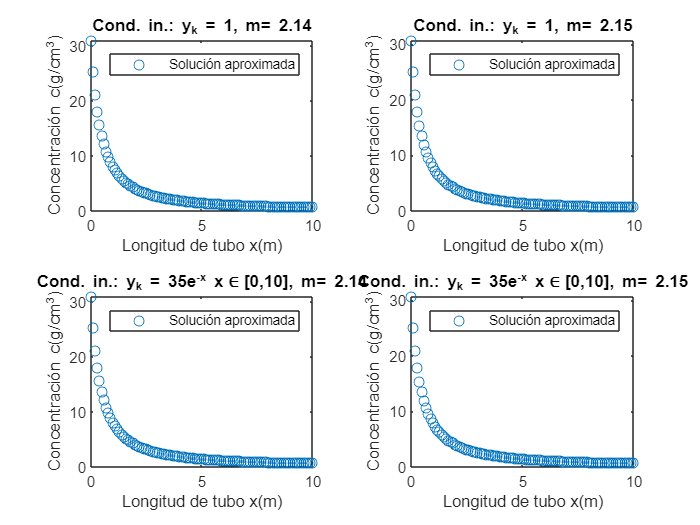

Converge en 407 iteraciones.


nexttile
grafica(2.15, n, 35*exp(-linspace(0,10,n+1)), maxit, @dfif, 'Cond. in.: y_k = 35e^{-x} x\in[0,10]')

**Observación para la clase:** 

- `m = 2.14, yk=ones(1,101)` converge en 344 iteraciones. `m=2.15` ya no converge en 400 iteraciones.

- Partir de una mejor solución inicial para `m = 2, yk=35*exp(-linspace(0,10,101))` hace que converjamos en 80 iteraciones (en vez de 92 partiendo de `ones()`).

### Algoritmo de Newton

Se trata de obtener una raíz del operador $\mathcal{G}:y\in\mathcal{C}_{bc}^2([a,b])\mapsto r\in\mathcal{C}([a,b])$ definido por:

    $r(x)=\mathcal{G}(y)(x) = y''(x) - u(x) - v(x)y^{m}(x)-w(x)y'(x)$* es el residuo de resolver la EDO*

*y *$\mathcal{C}_{bc}^2([a,b])$ es el conjunto de funciones de $\mathcal{C}^2([a,b]) $ que verifican las condiciones de contorno de [(P)](about:blank<#M_2CC8D053>)*.*

Por las propiedades del operador diferencial, 

$\mathcal{G}(y_{k+1})-\mathcal{G}(y_k) = D\mathcal{G}(y_k)[\delta y] +O((\delta y)^2)$,

donde $\delta y=y_{k+1}-y_k$. El algoritmo de Newton prescribe que $y_{k+1}$ sea la aproximación lineal de la raíz de $\mathcal{G}$, es decir, $y_{k+1}$ es la solución de $D\mathcal{G}(y_k)[\delta y](x) = -\mathcal{G}(y_k)(x)$.

Finalmente, el paso $k$ del algoritmo de Newton consiste en:

- Sea $y_k\in\mathcal{C}_{bc}^2([a,b])$ dado.

- Se calcula $y_{k+1}$ como solución de $D\mathcal{G}(y_k)[y_{k+1}-y_k](x) = -\mathcal{G}(y_k)(x)$.

- Si $\|y_{k+1}-y_k\|<\varepsilon$ ó $\|y_{k+1}''-u-vy_{k+1}^m - wy_{k+1}'\|<\varepsilon$ hay convergencia; si no, se sigue iterando.

#### Cálculo del operador diferencial $D\mathcal{G}(y)$

Puesto que $\mathcal{G}(y)(x) = y''(x) - u(x) - v(x)y^{m}(x)-w(x)y'(x)$, entonces 

$D\mathcal{G}(y)[\delta y](x) = \delta y''(x) - mv(x)y^{m-1}(x)\delta y(x)-w(x)\delta y'(x)$.

Por comodidad, omitiremos la dependencia en $x$. El paso 2. del algoritmo requiere resolver $D\mathcal{G}(y_k)[y_{k+1}-y_k]= -\mathcal{G}(y_k)$, es decir,

$(y_{k+1}-y_k)'' - mvy_k^{m-1}(y_{k+1}-y_k)-w(y_{k+1}-y_k)' = -y_k''+u+vy_k^m+wy_k'$,

$y_{k+1}'' = u +(1-m)vy_k^m+mvy_k^{m-1}y_{k+1}+wy_{k+1}'$. 

Si definimos $\tilde{u} = u + (1-m)vy_k^m, \ \tilde{v} = mvy_k^{m-1}$, entonces la EDO lineal $y_{k+1}'' = \tilde{u} + \tilde{v}y_{k+1}+wy_{k+1}'$ tendrá solución única en las condiciones dadas en [Keller](https://projecteuclid.org/journals/bulletin-of-the-american-mathematical-society-new-series/volume-72/issue-4/Existence-theory-for-two-point-boundary-value-problems/bams/1183528184.full).

### Implementación del algoritmo

La función `dfn` debe implementar el cálculo de la solución del problema discreto mediante el algoritmo de Newton. Los argumentos de entrada y salida coinciden con los de [`dfif`](matlab:open('./dfif.m')).

**Atención:** Las función `uN`, `vN` (que implementan las antedichas $\tilde u$, $\tilde{v}$) se deben declarar **dentro** de `dfn` para que puedan acceder a las variables actualizadas en el bucle iterativo.

### Ejercicio 3.3. Test académico para Newton

Considera el problema de contorno:


$$\left\{\begin{array}{ll}y''(t) = u(x)+y^m,\\-y'(0)+y(0)=1,\\y'(1) +y(1)= 2\text{e}+\cos(1)-\sin(1),\end{array}$$


siendo $u(x) = \mathrm{e}^x-\cos(x)-\left(\mathrm{e}^x+\cos(x)\right)^m$, con solución exacta $y(x) = \exp(x)+\cos(x)$.

- **Representa grá**`fi`**camente la solución exacta y la aproximada.**

Utiliza pasos $\Delta x= 0.1$ y $\Delta x = 0.01$. Identifica las gráfica e incluye en la leyenda las iteraciones realizad

%Solucion
clf
m = 2;
F = struct('u', @(x) exp(x)-cos(x)-(exp(x)+cos(x)).^m, ...
    'v', @(x)  ones(size(x)), ...
    'w', @(x) zeros(size(x)), ...
    'm', m);
bc = struct('blk_a', false, 'a', 0, 'ya', 1,                      'ha', 1, ...
    'blk_b', false, 'b', 1, 'yb', 2*exp(1)+cos(1)-sin(1), 'hb', 1);

%h = 0.01
n = (bc.b-bc.a)/0.01;
nl = struct('yk', ones(1,n+1), 'maxit', 400, 'tol', 1.e-6);
[x2, y2, k2] = dfn(F, bc, n, nl);

y =    -5.0000   -5.0300   -5.0600   -5.0900   -5.1200   -5.1501   -5.1801   -5.2102   -5.2403   -5.2704   -5.3006   -5.3308   -5.3610   -5.3913   -5.4216   -5.4520   -5.4825   -5.5130   -5.5437   -5.5743   -5.6051   -5.6360   -5.6670   -5.6981   -5.7293   -5.7606   -5.7921   -5.8237   -5.8554   -5.8873   -5.9194   -5.9516   -5.9841   -6.0167   -6.0495   -6.0825   -6.1158   -6.1493   -6.1830   -6.2170   -6.2513   -6.2858   -6.3206   -6.3557   -6.3911   -6.4269   -6.4630   -6.4995   -6.5363   -6.5735


y =   -10.2549  -10.3603  -10.4660  -10.5722  -10.6789  -10.7861  -10.8937  -11.0018  -11.1103  -11.2194  -11.3289  -11.4389  -11.5494  -11.6604  -11.7720  -11.8840  -11.9965  -12.1096  -12.2232  -12.3373  -12.4520  -12.5672  -12.6829  -12.7992  -12.9161  -13.0336  -13.1516  -13.2702  -13.3894  -13.5092  -13.6296  -13.7506  -13.8723  -13.9946  -14.1175  -14.2410  -14.3652  -14.4901  -14.6156  -14.7419  -14.8688  -14.9964  -15.1247  -15.2537  -15.3834  -15.5139  -15.6451  -15.7771  -15.9098  -16.0432


y =    -8.1854   -8.2583   -8.3315   -8.4048   -8.4784   -8.5522   -8.6262   -8.7005   -8.7751   -8.8499   -8.9250   -9.0005   -9.0762   -9.1522   -9.2285   -9.3052   -9.3822   -9.4596   -9.5373   -9.6154   -9.6939   -9.7728   -9.8521   -9.9319  -10.0121  -10.0928  -10.1739  -10.2555  -10.3377  -10.4204  -10.5036  -10.5873  -10.6717  -10.7566  -10.8422  -10.9284  -11.0152  -11.1028  -11.1910  -11.2800  -11.3696  -11.4601  -11.5513  -11.6434  -11.7363  -11.8300  -11.9247  -12.0202  -12.1167  -12.2142


y =    -8.0017   -8.0718   -8.1421   -8.2127   -8.2834   -8.3544   -8.4257   -8.4972   -8.5689   -8.6409   -8.7132   -8.7858   -8.8587   -8.9318   -9.0053   -9.0792   -9.1533   -9.2279   -9.3028   -9.3781   -9.4537   -9.5298   -9.6063   -9.6833   -9.7607   -9.8386   -9.9170   -9.9958  -10.0752  -10.1552  -10.2357  -10.3168  -10.3984  -10.4807  -10.5637  -10.6472  -10.7315  -10.8165  -10.9022  -10.9886  -11.0758  -11.1638  -11.2526  -11.3423  -11.4328  -11.5243  -11.6167  -11.7100  -11.8043  -11.8996


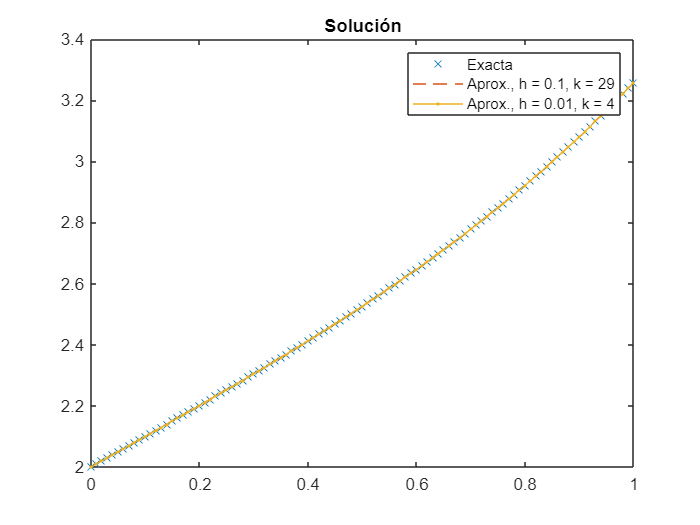

%grafica
sol = @(x) exp(x) + cos(x);
plot(x2,sol(x2),'x', ...
    x1,y1,'--', ...
    x2,y2,'.-')
title('Solución')
legend('Exacta', ['Aprox., h = 0.1, k = '  num2str(k1)], ...
    ['Aprox., h = 0.01, k = ' num2str(k2)])

- **Calcula la norma **$L^{\infty}(a,b)$** discreta del error absoluto y relativo para **$m\in [1, 2\ldots10]$**.**

%Solucion
sol = @(x) exp(x) + cos(x);

for m=1:10
    F = struct('u', @(x) exp(x)-cos(x)-(exp(x)+cos(x)).^m, ...
        'v', @(x)  ones(size(x)), ...
        'w', @(x) zeros(size(x)), ...
        'm', m);
    bc = struct('blk_a', false, 'a', 0, 'ya', 1,                      'ha', 1, ...
        'blk_b', false, 'b', 1, 'yb', 2*exp(1)+cos(1)-sin(1), 'hb', 1);

    %h = 0.01
    n = (bc.b-bc.a)/0.01;
    nl = struct('yk', ones(1,n+1), 'maxit', 400, 'tol', 1.e-6);
    [xn, yn, kn] = dfn(F, bc, n, nl);


    nor = normaInf(xn, yn, sol);
    norR = normaInfR(xn, yn, sol);

    disp(['Para m=' num2str(m) ' la norma infinito discreta del error absoluto es: ' num2str(nor) ' y la norma infinito discreta del error relativo es: ' num2str(norR) ...
        ' en k=' num2str(kn) ' iteraciones.'])
end

Para m=1 la norma infinito discreta del error absoluto es: 1.959e-05 y la norma infinito discreta del error relativo es: 3.005e-05 en k=1 iteraciones.
Para m=2 la norma infinito discreta del error absoluto es: 1.3911e-05 y la norma infinito discreta del error relativo es: 1.9761e-05 en k=4 iteraciones.
Para m=3 la norma infinito discreta del error absoluto es: 8.4648e-06 y la norma infinito discreta del error relativo es: 1.1347e-05 en k=6 iteraciones.
Para m=4 la norma infinito discreta del error absoluto es: 4.6008e-06 y la norma infinito discreta del error relativo es: 5.3594e-06 en k=10 iteraciones.
Para m=5 la norma infinito discreta del error absoluto es: 2.3875e-06 y la norma infinito discreta del error relativo es: 2.5199e-06 en k=15 iteraciones.
Para m=6 la norma infinito discreta del error absoluto es: 1.2095e-06 y la norma infinito discreta del error relativo es: 1.2664e-06 en k=22 iteraciones.
Para m=7 la norma infinito discreta del error absoluto es: 7.5646e-07 y la norma 

**Observación para la clase:** con $m$ desde 1 hasta 10, el número de iteraciones aumenta, pero converge.

### Ejercicio 3.4. Balance de masa de un reactor no lineal (Newton)

Considera el problema:


$$\left\{\begin{array}{l}
c''=\frac{\gamma}{D} c^m+ \frac{U}{D}\,c' ,\ x\in[0,L]\\
 -c'(0) +\frac{U}{D}c(0)= \frac{U}{D}c_{in} ,\\
c'(L) = 0.
\end{array}$$


- **Resuelve el problema anterior** **mediante diferencias finitas.** 

Usa los siguientes datos: $L=10\, \text{m}$, $D=1\,\text{m}^2/\text{h}$, $U=1\,\text{m}/\text{h}$, $\gamma=0.2$, $c_{in}=100\,\text{mol}/\text{m}^3$. 

%Solucion
L = 10; D = 1; U = 1; gm = 0.2; cin = 100;
F  = struct('u', @(x)   zeros(size(x)), ...
    'v', @(x) gm*(ones(size(x))).^m/D, ...
    'w', @(x)  U*ones(size(x))/D, ...
    'm', 2.14);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin/D, 'ha', U/D, ...
    'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);

%h = 0.01
n = (bc.b-bc.a)/0.1;
nl = struct('yk', ones(1,n+1), 'maxit', 400, 'tol', 1.e-6);
[xn, yn, kn] = dfn(F, bc, n, nl);

- **Compara gráficamente el resultado con el del caso lineal.**

%Solucion
F  = struct('u', @(x)   zeros(size(x)), ...
    'v', @(x) gm*(ones(size(x))).^m/D, ...
    'w', @(x)  U*ones(size(x))/D, ...
    'm', 1);
[xhL, yhL, ~ ] = dfn(F, bc, n, nl);

Operator '.^' is not supported for operands of type 'struct'.

Error in p3_dfnl (line 166)
    'v', @(x) gm*(ones(size(x))).^m/D, ...

Error in dfn/uN (line 34)
    y = F.u(x) + (1-F.m).* F.v(x).* nl.yk.^(F.m);

Error in 

clf
plot(xhL,yhL,'.', ...
    xn,yn,'.')
legend('Caso lineal','Caso no lineal')

- **Analiza la convergencia del algoritmo de iteración funcional para distintos valores de **$m$ **e iterantes iniciales.**

Utiliza la función [`grafica`](about:blank<#M_628E5FE1>).

%Solucion
n = 100;
maxit = 500;

% grafica(exponente, n de pasos, yk, maxit, algoritmo, labelyk)

tiledlayout('flow')
nexttile
grafica(4, n, ones(1,n+1), maxit, @dfn, 'Cond. in.: y_k = 1')

Converge en 15 iteraciones.


nexttile
grafica(4, n, ones(1,n+1), maxit, @dfn, 'Cond. in.: y_k = 1')

Converge en 15 iteraciones.


nexttile
grafica(4, n, 6*exp(-linspace(0,10,n+1)), maxit, @dfn, 'Cond. in.: y_k = 6e^{-x} x\in[0,10]')

Converge en 7 iteraciones.


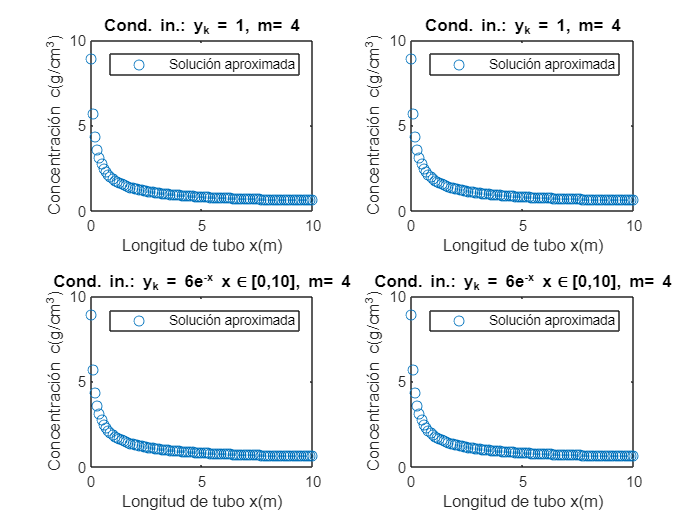

Converge en 7 iteraciones.


nexttile
grafica(4, n, 6*exp(-linspace(0,10,n+1)), maxit, @dfn, 'Cond. in.: y_k = 6e^{-x} x\in[0,10]')

**Observación para la clase:** 

- Para $m=4$, el usar $y_0= 6e^{-x}$ en vez de $y_0=1$reduce las iteraciones a la mitad.

## **Anexo. Funciones utilizadas en esta práctica**

En Matlab, las funciones utilizadas en un *script*, van al final de éste.

function v = normaInf(xh, yh, sol)
%NORMAINF   Calculo de la norma Loo discreta del error absoluto.

ye=sol(xh);
err=abs(ye-yh);
v=norm(err,'inf');
end

function v = norma2(xh, yh, sol)
%NORMA2   Calculo de la norma L2 discreta del error absoluto.
ye=sol(xh);
err=abs(ye-yh);
v=sqrt(trapz(xh,err.^2));
end

function v = normaInfR(xh, yh, sol)
%NORMAINF   Calculo de la norma Loo discreta del error relativo.

ye=sol(xh);
err=abs(ye-yh);
v = norm(err./max(abs(ye),eps));
end

function v = normaH1(xh, yh, sol)
%NORMAH1   Calculo de la norma H1 discreta del error absoluto.
h=(xh(end)-xh(1))/length(xh);

%Exactas
ye=sol(xh);

syms x
sol = exp(x) + cos(x);
dsol=matlabFunction(diff(sol));
y1e=dsol(xh(2:end-1));

%Aproximadas
yh;

d1 = @(y,h) (y(3:end)-y(1:end-2))/(2*h);            %aprox. primera derivada
y1a=d1(xh,h);

%Errores
err=abs(ye-yh);
err1=abs(y1a-y1e);

%Norma H1
v=sqrt(trapz(xh,err.^2)+trapz(xh(2:end-1),err1.^2));

end

function grafica(m, n, yk, maxit, algor, labelyk)
%GRAFICA   Grafica de la solucion aproximada para el balance de masa.

%Solucion
L = 10; D = 1; U = 1; gm = 0.2; cin = 100;
F  = struct('u', @(x)   zeros(size(x)), ...
    'v', @(x) gm*(ones(size(x))).^m/D, ...
    'w', @(x)  U*ones(size(x))/D, ...
    'm', m);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin/D, 'ha', U/D, ...
    'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);


nl = struct('yk', yk, 'maxit', maxit, 'tol', 1.e-6);
[xh, yh, k] = algor(F, bc, n, nl);

plot(xh,yh,'o')
title([labelyk,', m= ',num2str(m)])
xlabel('Longitud de tubo x(m)')
ylabel('Concentración c(g/cm^3)')
legend('Solución aproximada')
disp(['Converge en ' num2str(k) ' iteraciones.'])

end